%{ 
Group 3:
1. Steve Vinsensius Jo - V01099466
2. Likkhith Krishnamurthy Aditya - V01098937
%}

Task 1:

Develop a matlab function that creates K samples of D-dimensional Gaussian data with arbitrary specified mean μ and covariance matrix Σ.

rng(537);
function [X_transformed, genMean, genCov] = generateGaussian(mu,sigma,K)
% mu = Dx1 matrix
% sigma = DxD matrix
% K = number of samples

% generating samples
dimension = length(mu);
samples = randn(K,dimension);

Xmean = mean(samples);
Xcov = cov(samples);

% Phi (φ) and lambda (λ)
% phi_X: eigenvectors (dxd)
% lambda_X: diagonal matrix of eigenvalues (dxd)
[phi_X, lambda_X] = eig(Xcov);

% center the mean
X_centered = samples - Xmean;

% whitening transform
T_W = phi_X * diag(1 ./ sqrt(diag(lambda_X)));  % Φ Λ^(-1/2)

% whitening
X_white = X_centered * T_W;

% check the whitening
X_white_cov = cov(X_white);
X_white_mean = mean(X_white);
disp("Sanity Check");
disp("Whitening Mean:");
disp(X_white_mean);
disp("Whitening Covariance:");
disp(X_white_cov);

% inverse whitening transform onto the target covariance
[phi, lambda] = eig(sigma);
X_transformed = X_white * diag(sqrt(diag(lambda))) * phi' + mu';

genMean = mean(X_transformed);
genCov = cov(X_transformed);
end

% test if the function is working
mu = [0; 4; 7];
sigma = [6.5000, 2.1651, 1.2500; 2.1651, 5.1250, 2.3816; 1.2500, 2.3816, 2.3750];
K = 10;
[test_samples,test_mean,test_cov] = generateGaussian(mu,sigma,K);

Sanity Check
Whitening Mean:
   1.0e-15 *

   -0.1776    0.0444    0.0111

Whitening Covariance:
    1.0000   -0.0000   -0.0000
   -0.0000    1.0000    0.0000
   -0.0000    0.0000    1.0000



disp("Samples");

Samples


disp(test_samples);

    0.2841    4.1898    7.5115
   -1.9389    4.4302    7.7824
    0.3181    5.6605    8.1812
    0.5523    1.7930    5.2235
    1.7879    3.7650    5.9784
   -3.9848    0.7696    3.6586
    5.3222    6.7681    7.9698
    1.0376    1.7801    7.4382
   -1.8753    3.0606    8.3053
   -1.5031    7.7831    7.9512



disp("Mean:");

Mean:


disp(test_mean);

   -0.0000    4.0000    7.0000



disp("Covariance:");

Covariance:


disp(test_cov);

    6.5000    2.1651    1.2500
    2.1651    5.1250    2.3816
    1.2500    2.3816    2.3750



Task 2

Fully test your developed function to ensure that it indeed produces D-dimensional Gaussian data with the correct mean vector and covariance matrix.

% To prove the mean and covariance is correct,
% the answer should be around 10^-15 to 10^-16 difference
disp(max(abs(test_mean(:) - mu(:))));

   6.6613e-17



disp(max(max(abs(test_cov - sigma))));

   3.5527e-15




% --- larger K, random covariance, higher D ---
mu_T = [1; -2; 3; 0];
A = randn(4);
sigma_T = A*A' + 4*eye(4);
[Xt, mt, ct] = generateGaussian(mu_T, sigma_T, 5000);

Sanity Check
Whitening Mean:
   1.0e-16 *

   -0.0142    0.2700    0.0284    0.1172

Whitening Covariance:
    1.0000    0.0000   -0.0000   -0.0000
    0.0000    1.0000   -0.0000   -0.0000
   -0.0000   -0.0000    1.0000    0.0000
   -0.0000   -0.0000    0.0000    1.0000



disp("Mean error:"); disp(max(abs(mt(:) - mu_T(:))));

Mean error:
   2.2204e-15



disp("Cov error:");  disp(max(max(abs(ct - sigma_T))));

Cov error:
   9.7700e-15




% --- is it actually GAUSSIAN? squared Mahalanobis distance ~ chi2(D) ---
diffs = Xt - mu_T';
d2 = sum((diffs / sigma_T) .* diffs, 2);
fprintf('mean(d2) = %.3f (theory 4)\n', mean(d2));

mean(d2) = 3.999 (theory 4)


fprintf('var(d2)  = %.3f (theory 8)\n', var(d2));

var(d2)  = 7.749 (theory 8)


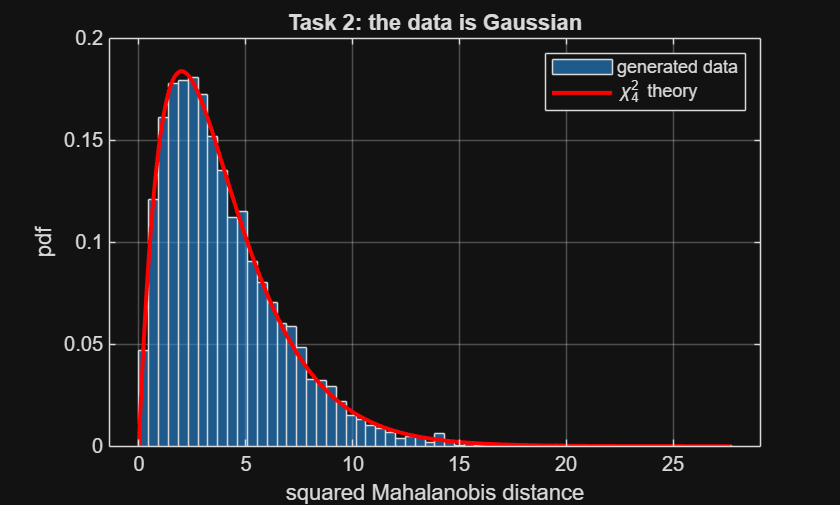


figure;
histogram(d2, 60, 'Normalization', 'pdf'); hold on;
t = linspace(0, max(d2), 300);
plot(t, chi2pdf(t, 4), 'r', 'LineWidth', 2);
xlabel('squared Mahalanobis distance'); ylabel('pdf');
legend('generated data','\chi^2_4 theory');
title('Task 2: the data is Gaussian'); grid on;

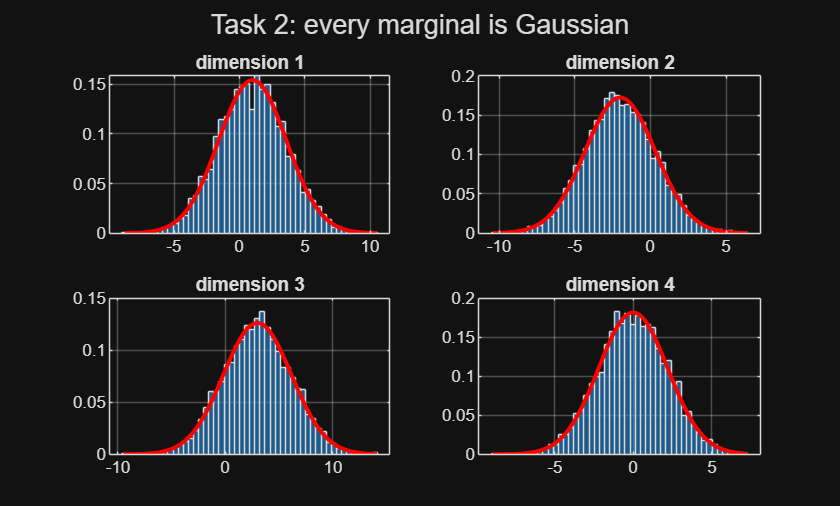


% --- each marginal should also be Gaussian ---
figure;
for d = 1:4
    subplot(2,2,d);
    histogram(Xt(:,d), 50, 'Normalization', 'pdf'); hold on;
    xg = linspace(min(Xt(:,d)), max(Xt(:,d)), 200);
    plot(xg, normpdf(xg, mu_T(d), sqrt(sigma_T(d,d))), 'r', 'LineWidth', 2);
    title(sprintf('dimension %d', d)); grid on;
end
sgtitle('Task 2: every marginal is Gaussian');


% --- works for arbitrary D ---
for D = 1:5
    muD = (1:D)'; Ad = randn(D); sigD = Ad*Ad' + eye(D);
    [Xd, md, cdd] = generateGaussian(muD, sigD, 2000);
    fprintf('D = %d : mean err = %.2e, cov err = %.2e\n', ...
            D, max(abs(md(:)-muD)), max(max(abs(cdd - sigD))));
end

Sanity Check
Whitening Mean:
  -3.1974e-17

Whitening Covariance:
    1.0000



D = 1 : mean err = 3.33e-16, cov err = 0.00e+00


Sanity Check
Whitening Mean:
   1.0e-16 *

    0.0711    0.1155

Whitening Covariance:
    1.0000   -0.0000
   -0.0000    1.0000



D = 2 : mean err = 4.44e-16, cov err = 1.78e-15


Sanity Check
Whitening Mean:
   1.0e-16 *

    0.3553    0.1688   -0.2309

Whitening Covariance:
    1.0000   -0.0000    0.0000
   -0.0000    1.0000   -0.0000
    0.0000   -0.0000    1.0000



D = 3 : mean err = 8.88e-16, cov err = 9.77e-15


Sanity Check
Whitening Mean:
   1.0e-16 *

    0.0266    0.2487    0.2309    0.0500

Whitening Covariance:
    1.0000   -0.0000   -0.0000    0.0000
   -0.0000    1.0000   -0.0000    0.0000
   -0.0000   -0.0000    1.0000   -0.0000
    0.0000    0.0000   -0.0000    1.0000



D = 4 : mean err = 2.22e-15, cov err = 3.55e-15


Sanity Check
Whitening Mean:
   1.0e-16 *

    0.2487   -0.5795   -0.0566   -0.1066    0.0711

Whitening Covariance:
    1.0000    0.0000    0.0000   -0.0000   -0.0000
    0.0000    1.0000    0.0000    0.0000   -0.0000
    0.0000    0.0000    1.0000   -0.0000    0.0000
   -0.0000    0.0000   -0.0000    1.0000   -0.0000
   -0.0000   -0.0000    0.0000   -0.0000    1.0000



D = 5 : mean err = 3.55e-15, cov err = 7.11e-15



% --- separate calls must be independent ---
c1 = generateGaussian([0;0;0], eye(3), 1000);

Sanity Check
Whitening Mean:
   1.0e-16 *

    0.4935   -0.4619    0.1510

Whitening Covariance:
    1.0000    0.0000   -0.0000
    0.0000    1.0000   -0.0000
   -0.0000   -0.0000    1.0000



c2 = generateGaussian([0;0;0], eye(3), 1000);

Sanity Check
Whitening Mean:
   1.0e-16 *

    0.2753   -0.4263   -0.0355

Whitening Covariance:
    1.0000   -0.0000   -0.0000
   -0.0000    1.0000   -0.0000
   -0.0000   -0.0000    1.0000



fprintf('independence: max|c1-c2| = %.3f (must NOT be ~1e-15)\n', max(max(abs(c1-c2))));

independence: max|c1-c2| = 5.464 (must NOT be ~1e-15)


Task 3

Discuss why, when K < ∞, the Matlab’s computed covariance matrix for your Gaussian generated data will not exactly match the covariance you prescribed.

%{
Because Matlab randn takes random samples from Gaussian distribution (0 mean and 1 standard deviation). 
When we are using cov() and mean(), we are only calculating from finite K samples from the distribution.
Therefore, the mean and covariance calculated in the function will not be
the true mean and true covariance as long as K is less than infinity.
%}

Task 4

mu_A = [0; 4; 7];
sigma_A = [6.5000, 2.1651, 1.2500; 2.1651, 5.1250, 2.3816; 1.2500, 2.3816, 2.3750];
mu_B = [10; 5; 5];
sigma_B = [3.0184, 0.4331, -1.4481; 0.4331, 0.9436, -0.6456; -1.4481, -0.6456, 1.2880];
mu_C = [-2; -5; -5];
sigma_C = [6.8928, -1.3750, 3.1945; -1.3750, 3.3572, 0.6945; 3.1945, 0.6945, 3.7500];
K = 1000;
disp("Class A")

Class A


[samples_A,mean_A,cov_A] = generateGaussian(mu_A,sigma_A,K);

Sanity Check
Whitening Mean:
   1.0e-16 *

   -0.7594   -0.2842    0.0711

Whitening Covariance:
    1.0000    0.0000   -0.0000
    0.0000    1.0000    0.0000
   -0.0000    0.0000    1.0000



disp("Samples");

Samples


disp(samples_A);

    0.4085    3.6705    5.2772
   -0.4996    4.2203    7.1622
   -0.1024    1.8239    7.6092
   -2.0123    8.0338    8.0233
   -0.3782    6.9798    8.4211
   -1.6395    3.4188    7.1321
    0.8311    6.6885    5.2880
   -3.4869    5.7815    9.2270
    2.7449    5.5770    8.0102
    0.7571    6.1162    7.4722
    1.1777    3.6126    8.5734
    3.6229    2.1565    5.6711
   -1.9941    4.5112    7.4767
    3.0662    6.8640    7.5463
    0.7524    4.9046    6.2861
    1.3009    4.6107    7.7885
    2.7431    3.6573    6.5970
    3.1873    5.6861    7.2430
   -2.7433   -1.4135    4.2012
   -0.5156    2.1956    5.7802
   -0.9719    6.0377    9.1805
   -1.3199    6.0415   11.0725
   -2.0473    5.1051    7.8077
    1.7306    8.8766   11.9329
   -2.7219    5.0999    5.9025
    4.6650    2.9823    7.6513
    1.9762   -3.3632    2.6088
   -0.2831    5.2901    7.3008
   -0.5017    3.4757    6.1095
   -3.8183    6.9627    8.9156
   -1.5806    0.8948    5.3615
   -1.7828    2.4296    5.8206
    0.99

disp("Mean:");

Mean:


disp(mean_A);

    0.0000    4.0000    7.0000



disp("Covariance:");

Covariance:


disp(cov_A);

    6.5000    2.1651    1.2500
    2.1651    5.1250    2.3816
    1.2500    2.3816    2.3750



disp("Class B")

Class B


[samples_B,mean_B,cov_B] = generateGaussian(mu_B, sigma_B, K);

Sanity Check
Whitening Mean:
   1.0e-16 *

    0.1910    0.0266    0.0799

Whitening Covariance:
    1.0000   -0.0000    0.0000
   -0.0000    1.0000    0.0000
    0.0000    0.0000    1.0000



disp("Samples");

Samples


disp(samples_B);

    9.1838    5.1531    5.9558
    7.3076    4.7533    6.6076
    9.3168    4.7737    6.1054
   12.4530    6.3346    1.7509
   11.1876    3.8959    4.7091
    8.7767    2.9529    6.8511
    8.2392    3.4529    6.8976
    9.0697    5.1216    5.3795
    9.1762    4.1840    6.3135
   10.3101    4.8881    5.1721
   10.0312    6.1356    4.8749
    9.2727    4.0724    5.5497
   11.7776    4.1395    4.7380
    8.9560    5.7202    5.6622
   11.2970    5.4266    4.3253
   10.8592    4.9017    4.1595
    8.8361    5.1902    4.9181
   11.6534    7.2794    2.1045
    9.6407    4.6876    5.7710
   11.6233    3.2029    5.2122
    9.7361    5.6147    4.8355
    9.4793    4.5039    6.4015
   11.0536    4.8275    4.2605
   10.7571    3.6327    5.6336
   13.0367    5.9372    3.4023
   11.4568    3.4860    5.6962
   10.7198    5.8334    4.7260
   10.9331    4.5427    4.8787
   12.3128    5.9328    4.6728
   11.0189    5.9859    4.4006
   11.4440    6.8726    4.1463
    8.1158    3.8421    6.5622
   10.33

disp("Mean:");

Mean:


disp(mean_B);

   10.0000    5.0000    5.0000



disp("Covariance:");

Covariance:


disp(cov_B);

    3.0184    0.4331   -1.4481
    0.4331    0.9436   -0.6456
   -1.4481   -0.6456    1.2880



disp("Class C")

Class C


[samples_C,mean_C,cov_C] = generateGaussian(mu_C, sigma_C, K);

Sanity Check
Whitening Mean:
   1.0e-16 *

    0.1937   -0.5684   -0.0178

Whitening Covariance:
    1.0000    0.0000    0.0000
    0.0000    1.0000    0.0000
    0.0000    0.0000    1.0000



disp("Samples");

Samples


disp(samples_C);

   -2.4352   -7.4408   -6.5703
   -1.5303   -4.7770   -4.3169
    3.0825   -9.4807   -5.3401
    1.1873   -5.2376   -4.5076
   -2.1642   -4.7901   -5.0465
    0.8286   -6.7831   -3.1105
   -0.7265   -5.4935   -4.9701
    5.7557   -9.1011   -2.8083
    1.5396   -5.5639   -3.3085
    0.9656   -7.1980   -2.1029
   -7.8812   -2.5390   -6.7755
    1.7731   -5.0179   -5.5950
    4.0841   -5.7409   -0.6940
   -9.1602   -5.0231   -9.8647
   -0.9258   -5.0657   -5.7924
   -0.5729   -4.6928   -3.6493
   -0.8022   -3.9448   -3.3887
    0.9328   -5.7032   -3.6403
   -3.9683   -4.5712   -5.2911
   -5.0318   -4.2475   -8.8105
   -3.0839   -7.2010   -7.8895
   -4.8766   -2.2946   -8.0960
   -0.1423   -4.3397   -3.4132
   -4.4849   -5.4570   -7.1357
   -3.6391   -3.6603   -6.6707
   -3.6285   -6.7819   -5.0490
   -1.5962   -3.5199   -4.5138
    1.8878  -10.9784   -2.8360
    2.6139   -6.4412   -3.4411
   -3.3760   -2.6503   -3.9489
    0.1198   -6.6687   -6.0769
    3.2849   -5.6363   -1.7623
   -1.00

disp("Mean:");

Mean:


disp(mean_C);

   -2.0000   -5.0000   -5.0000



disp("Covariance:");

Covariance:


disp(cov_C);

    6.8928   -1.3750    3.1945
   -1.3750    3.3572    0.6945
    3.1945    0.6945    3.7500




% Comparing to true mean and true covariance
disp("Comparing True and Calculated Mean and Covariance")

Comparing True and Calculated Mean and Covariance


disp("Mean diff (Class A):"); disp(max(abs(mean_A(:) - mu_A(:))));

Mean diff (Class A):
   6.7502e-17



disp("Cov diff (Class A):"); disp(max(max(abs(cov_A - sigma_A))));

Cov diff (Class A):
   2.6645e-15



disp("Mean diff (Class B):"); disp(max(abs(mean_B(:) - mu_B(:))));

Mean diff (Class B):
   8.8818e-16



disp("Cov diff (Class B):"); disp(max(max(abs(cov_B - sigma_B))));

Cov diff (Class B):
   1.1102e-15



disp("Mean diff (Class C):"); disp(max(abs(mean_C(:) - mu_C(:))));

Mean diff (Class C):
   2.6645e-15



disp("Cov diff (Class C):"); disp(max(max(abs(cov_C - sigma_C))));

Cov diff (Class C):
   3.9968e-15



Task 5

disp("Comparing generateGaussian vs mvnrnd")

Comparing generateGaussian vs mvnrnd


mvn_A = mvnrnd(mu_A', sigma_A, K);
mvn_B = mvnrnd(mu_B', sigma_B, K);
mvn_C = mvnrnd(mu_C', sigma_C, K);

mvnMean_A = mean(mvn_A); mvnCov_A = cov(mvn_A);
mvnMean_B = mean(mvn_B); mvnCov_B = cov(mvn_B);
mvnMean_C = mean(mvn_C); mvnCov_C = cov(mvn_C);

disp("mvnrnd Mean diff (Class A):"); disp(max(abs(mvnMean_A(:) - mu_A(:))));

mvnrnd Mean diff (Class A):
    0.1528



disp("mvnrnd Cov diff (Class A):"); disp(max(max(abs(mvnCov_A - sigma_A))));

mvnrnd Cov diff (Class A):
    0.2100



disp("mvnrnd Mean diff (Class B):"); disp(max(abs(mvnMean_B(:) - mu_B(:))));

mvnrnd Mean diff (Class B):
    0.0641



disp("mvnrnd Cov diff (Class B):"); disp(max(max(abs(mvnCov_B - sigma_B))));

mvnrnd Cov diff (Class B):
    0.1616



disp("mvnrnd Mean diff (Class C):"); disp(max(abs(mvnMean_C(:) - mu_C(:))));

mvnrnd Mean diff (Class C):
    0.0722



disp("mvnrnd Cov diff (Class C):"); disp(max(max(abs(mvnCov_C - sigma_C))));

mvnrnd Cov diff (Class C):
    0.1551



Indeed, the results are similar. The two data sets have an intersection when graphed and have sample mean and covariances that are similar up to two decimal places. They both have valid Gaussian data with the desired distribution.

Why are they not the same?

mvnrnd colour the original randn samples without forcing the sample covariance matrix to be the identity first. They use different draws from the random number stream, hence they are not using the same samples.

Which of the two functions generated data with the required covariances?

generateGaussian. The covariance error for it is of the order of 1e-15, that is, floating point rounding error. The mvnrnd-like generator is off by a couple of hundredths to a couple of tenths.

Why should we generate data with exactly the required covariance?

If the covariance is approximately correct, then the discrepancy between the boundary calculated by the code and the expected boundary can be due to either of the two reasons: coding error or sampling error. There is no way to differentiate between them. With exact covariance, the sample based solution is identical to the theoretical one.

Task 6

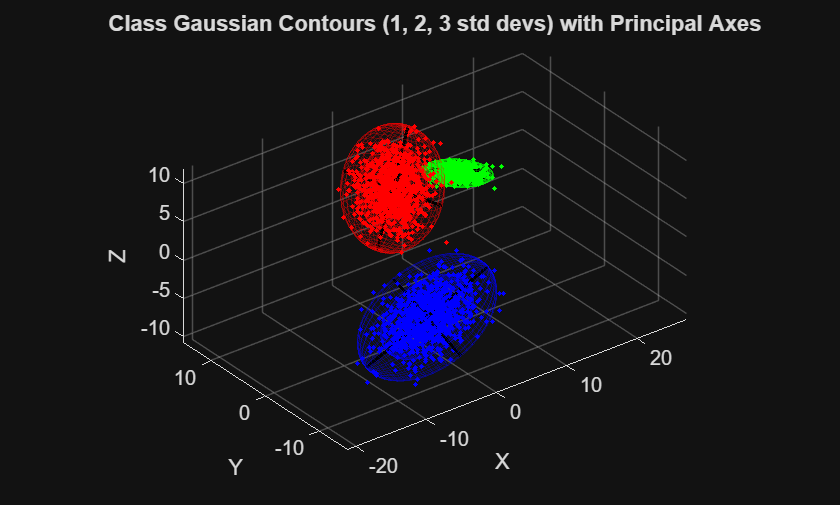

% Function for ellipsoid
function plotGaussianEllipsoid(mu, sigma, color, nStdList)
% mu = Dx1
% sigma = DxD
% color = plot color
% nStdList = e.g. [1 2 3]

[phi, lambda] = eig(sigma);
eigVals = diag(lambda);

hold on;

for n = nStdList
    % generate unit sphere
    [X, Y, Z] = ellipsoid(0,0,0,1,1,1,30);
    pts = [X(:), Y(:), Z(:)]; % (numPoints x 3)

    % scale by n*sqrt(eigenvalues), rotate by eigenvectors, shift by mu
    scaled = pts * diag(n * sqrt(eigVals));
    rotated = scaled * phi';
    shifted = rotated + mu';

    % reshape back to grid for surf plotting
    Xe = reshape(shifted(:,1), size(X));
    Ye = reshape(shifted(:,2), size(Y));
    Ze = reshape(shifted(:,3), size(Z));

    surf(Xe, Ye, Ze, 'FaceColor', 'none', 'EdgeColor', color, 'EdgeAlpha', 0.3);
end

% principal axes: one line per eigenvector, length = 3*sqrt(eigenvalue) 
% (using 3 std so the longest ellipsoid is fully spanned)
for i = 1:length(eigVals)
    axisVec = phi(:,i) * 3 * sqrt(eigVals(i));
    p1 = mu - axisVec;
    p2 = mu + axisVec;
    line([p1(1) p2(1)], [p1(2) p2(2)], [p1(3) p2(3)], 'Color', 'k', 'LineWidth', 1.5);
end

end

% Class Gaussian Contour with 1,2, and 3 standard deviations
figure;
% Red = Class A; Green = Class B; Blue = Class C;
plotGaussianEllipsoid(mu_A, sigma_A, 'r', [1 2 3]);
plotGaussianEllipsoid(mu_B, sigma_B, 'g', [1 2 3]);
plotGaussianEllipsoid(mu_C, sigma_C, 'b', [1 2 3]);
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Class Gaussian Contours (1, 2, 3 std devs) with Principal Axes');
grid on; axis equal; view(3);

scatter3(samples_A(:,1), samples_A(:,2), samples_A(:,3), 5, 'r', 'filled');
scatter3(samples_B(:,1), samples_B(:,2), samples_B(:,3), 5, 'g', 'filled');
scatter3(samples_C(:,1), samples_C(:,2), samples_C(:,3), 5, 'b', 'filled');

Task 7:

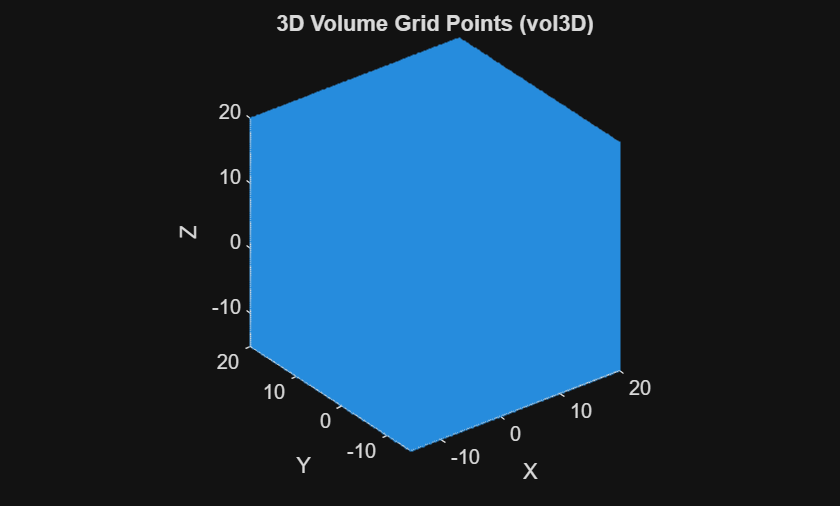

allSamples = [samples_A; samples_B; samples_C];

% buffer = 2;
% xMin = min(allSamples(:,1)) - buffer; xMax = max(allSamples(:,1)) + buffer;
% yMin = min(allSamples(:,2)) - buffer; yMax = max(allSamples(:,2)) + buffer;
% zMin = min(allSamples(:,3)) - buffer; zMax = max(allSamples(:,3)) + buffer;

% Vaxis = [xMin xMax yMin yMax zMin zMax];
Vaxis = [-15 20 -15 20 -15 20];
Num = 120;

gridPoints = vol3D(Vaxis, Num);

% visualize the grid
figure;
plot3(gridPoints(:,1), gridPoints(:,2), gridPoints(:,3), '.', 'MarkerSize', 1);
xlabel('X'); ylabel('Y'); zlabel('Z');
title('3D Volume Grid Points (vol3D)');
grid on; axis equal;

Task 8:


$$g_i(\mathbf{x}) = -\frac{1}{2} (\mathbf{x} - {\mu}_i)^T \mathbf{\Sigma}_i^{-1} (\mathbf{x} - {\mu}_i) - \frac{1}{2} \ln |\mathbf{\Sigma}_i|$$


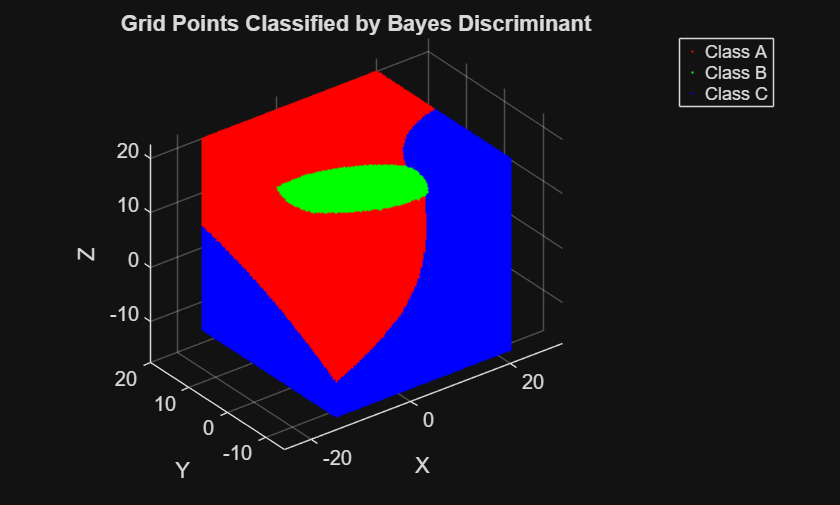

% Bayes Discriminant function
function g = discriminant(X, mu, sigma)
% X = N x D matrix of points
% mu = D x 1 mean vector
% sigma = D x D covariance matrix
% returns g = N x 1 vector of discriminant scores

D = size(X,1);
Xc = X - mu';

invSigma = inv(sigma);
logDetSigma = log(det(sigma));

% vectorized Mahalanobis distance
quadForm = sum((Xc * invSigma) .* Xc, 2);

g = -0.5 * quadForm - 0.5 * logDetSigma;

end

g_A = discriminant(gridPoints, mu_A, sigma_A);
g_B = discriminant(gridPoints, mu_B, sigma_B);
g_C = discriminant(gridPoints, mu_C, sigma_C);

allG = [g_A, g_B, g_C]; % N x 3
% Nx1 output
% 1 = Class A; 2 = Class B; 3 = Class C
[~, classLabels] = max(allG, [], 2);

% visualization
figure;
colors = {'r','g','b'};
hold on;
for c = 1:3
    mask = classLabels == c;
    plot3(gridPoints(mask,1), gridPoints(mask,2), gridPoints(mask,3), ...
        '.', 'Color', colors{c}, 'MarkerSize', 2);
end
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Grid Points Classified by Bayes Discriminant');
grid on; axis equal; view(3);
legend('Class A','Class B','Class C');

Task 9

sortedG = sort(allG, 2, 'descend');
topGap = sortedG(:,1) - sortedG(:,2);

epsilon = 0.1;
boundaryMask = abs(topGap) < epsilon;
boundaryPoints = gridPoints(boundaryMask, :);

fprintf("Number of boundary points found: %d\n", size(boundaryPoints,1));

Number of boundary points found: 3160


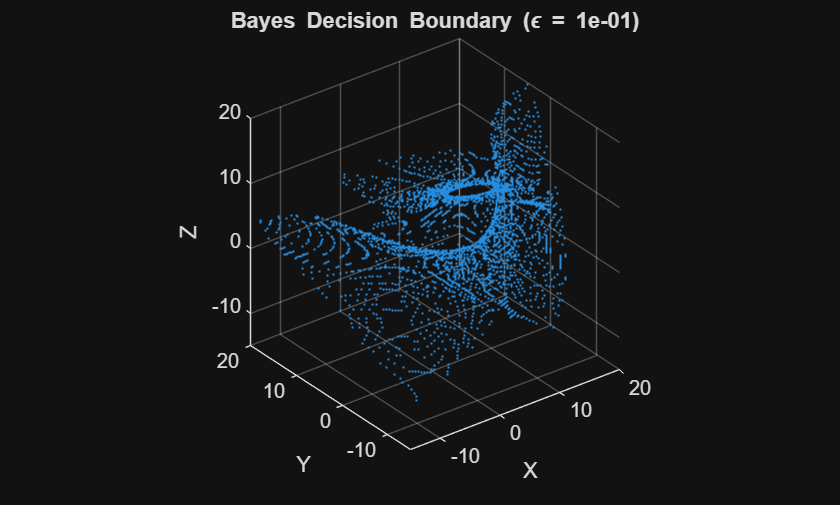


% visualization
figure;
plot3(boundaryPoints(:,1), boundaryPoints(:,2), boundaryPoints(:,3), '.', 'MarkerSize', 3);
xlabel('X'); ylabel('Y'); zlabel('Z');
title(sprintf('Bayes Decision Boundary (\\epsilon = %.0e)', epsilon));
grid on; axis equal; view(3);


disp(min(topGap));

   4.3490e-05



epsilon=1e-02 -> 313 points
epsilon=5e-02 -> 1565 points
epsilon=1e-01 -> 3160 points
epsilon=3e-01 -> 9238 points
epsilon=5e-01 -> 15349 points


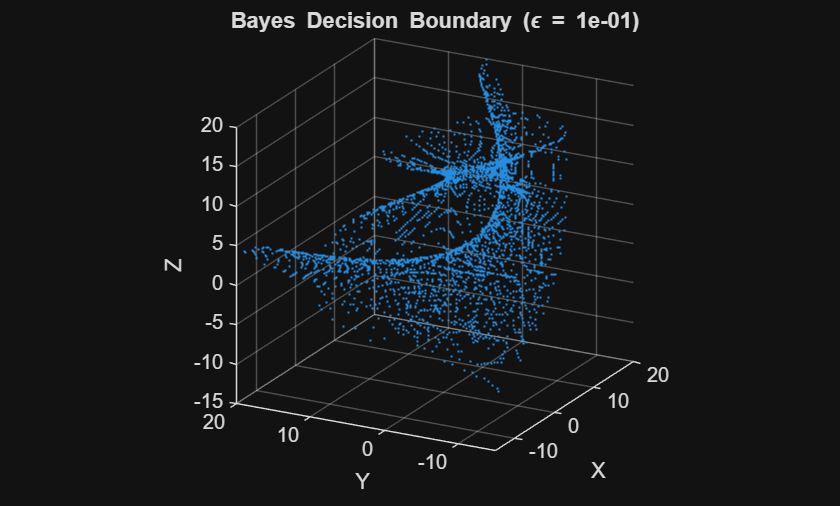

for eps_test = [1e-2, 5e-2, 1e-1, 3e-1, 5e-1]
    n = sum(topGap < eps_test);
    fprintf("epsilon=%.0e -> %d points\n", eps_test, n);
end

% Task 10

This produced boundary corresponds to the boundary plotted in the figure attached to the ECE 537 Brightspace site. Both figures show two curved boundaries: one for separating classes A and B, which is a sloping sheet, and one for separating classes A and C, which is a dome-shaped boundary. There is no boundary shown for separating B and C classes since class A is in between these two classes, and their volumes do not intersect each other.

The only difference that one can see here is the density of points. For this particular volume, we use Num = 120 on the range [-15, 20] for sampling the volume, resulting in a grid size of 0.294 with 3,200 boundary points. The number of grid points falling within epsilon distance from a boundary depends on the grid size, so the smaller the grid size, the greater number of points we obtain.

For the epsilon threshold, we refer to the handout and take epsilon in the range [1e-4, 1e-2]. However, this range produces very few points on this grid, so we choose epsilon = 0.1.

Some of the criteria used to confirm that there were no mistakes in the code were the following:

- the covariance matrices are calculated correctly up to about 1e-15;

- the discriminant function takes into account the value -0.5*log(det(sigma));

- there is no need to use fixed two discriminants when testing boundaries since in case of two classes having equal discriminants the one with the best result is taken into account;

- the sampling volume includes three distributions up to three standard deviations.